# Partial Differential Equations

Partial differential equation is a class of differential equations involving more than one independent variable. In this chapter, we consider a general second-order PDE in two independent variables $x$ and $y$, which is written as


$$A\left(x,y\right)\frac{\partial^2 u}{{\partial x}^2 }+B\left(x,y\right)\frac{\partial^2 u}{\partial x\partial y}+C\left(x,y\right)\frac{\partial^2 u}{{\partial y}^2 }=f\left(x,y,u,\frac{\partial u}{\partial x},\frac{\partial u}{\partial y}\right)$$


for $x_0 \le x\le x_f$ and $y_0 \le y\le y_f$

with the boundary conditions given by 


$$u\left(x_0 ,y\right)=b_{\textrm{x0}} \left(y\right)$$



$$u\left(x_f ,y\right)=b_{\textrm{xf}} \left(y\right)$$



$$u\left(x,y_0 \right)=b_{\textrm{y0}} \left(x\right)$$



$$u\left(x,y_f \right)=b_{\textrm{yf}} \left(x\right)$$


These PDEs can be classified into three groups:

Elliptic PDE: if $B^2 -4\textrm{AC}<0$

Parabolic PDE: if $B^2 -4\textrm{AC}=0$

Hyperbolic PDE: if $B^2 -4\textrm{AC}>0$

## Elliptic PDE - Poisson and Laplace's equation

In this livescript, we consider a special type of an elliptic PDE, called the Helmholtz's equation, which is written as


$$\nabla^2 u\left(x,y\right)+g\left(x,y\right)u\left(x,y\right)=f\left(x,y\right)$$


or


$$\frac{\partial^2 u\left(x,y\right)}{{\partial x}^2 }+\frac{\partial^2 u\left(x,y\right)}{{\partial y}^2 }+g\left(x,y\right)u\left(x,y\right)=f\left(x,y\right)$$


for $x_0 \le x\le x_f$ and $y_0 \le y\le y_f$

with the boundary conditions given by 


$$u\left(x_0 ,y\right)=b_{\textrm{x0}} \left(y\right)$$



$$u\left(x_f ,y\right)=b_{\textrm{xf}} \left(y\right)$$



$$u\left(x,y_0 \right)=b_{\textrm{y0}} \left(x\right)$$



$$u\left(x,y_f \right)=b_{\textrm{yf}} \left(x\right)$$


It is called Poisson's equation if $g\left(x,y\right)=0$ and it is called Laplace's equation if $g\left(x,y\right)=0$ and $f\left(x,y\right)=0$.

We apply the difference method to the PDE and replace the second derivatives by the three-point central difference approximation

${\frac{\partial^2 u\left(x,y\right)}{{\partial x}^2 }|}_{x_j ,y_i } \cong \frac{u_{i,j+1} -2u_{i,j} +u_{i,j-1} }{{\Delta x}^2 }$ and ${\frac{\partial^2 u\left(x,y\right)}{{\partial y}^2 }|}_{x_j ,y_i } \cong \frac{u_{i+1,j} -2u_{i,j} +u_{i-1,j} }{{\Delta y}^2 }$

where $u_{i,j} =u\left(x_j ,y_i \right)$. Here, we divide the whole domain into $M_x$ and $M_y$ sections, where

$\Delta x=\frac{x_f -x_0 }{M_x }$ and $\Delta y=\frac{y_f -y_0 }{M_y }$ along the $x-$ and $y-$axis, respectively. We obtain each coordinate point from

$x_j =x_0 +j\Delta x$ and $y_i =y_0 +i\Delta y$ along the $x-$ and $y-$axis, respectively. Thus, we rewite the PDE as


$$\frac{u_{i,j+1} -2u_{i,j} +u_{i,j-1} }{{\Delta x}^2 }+\frac{u_{i+1,j} -2u_{i,j} +u_{i-1,j} }{{\Delta y}^2 }+g_{i,j} u_{i,j} =f_{i,j}$$


where $u_{i,j} =u\left(x_j ,y_i \right)$, $f_{i,j} =f\left(x_j ,y_i \right)$, and $g_{i,j} =g\left(x_j ,y_i \right)$. This equation can be rearranged into the following form


$$u_{i,j} =r_y \left(u_{i,j+1} +u_{i,j-1} \right)+r_x \left(u_{i+1,j} +u_{i-1,j} \right)+r_{\textrm{xy}} \left(g_{i,j} u_{i,j} -f_{i,j} \right)$$


where

$r_y =\frac{{\Delta y}^2 }{2\left({\Delta x}^2 +{\Delta y}^2 \right)}$, $r_x =\frac{{\Delta x}^2 }{2\left({\Delta x}^2 +{\Delta y}^2 \right)}$, and $r_{\textrm{xy}} =\frac{{\Delta x}^2 {\Delta y}^2 }{2\left({\Delta x}^2 +{\Delta y}^2 \right)}$

with the following boundary conditions

$u_{i,0} =b_{\textrm{x0}} \left(y_i \right)$, $u_{i,M_x } =b_{\textrm{xf}} \left(y_i \right)$, $u_{0,j} =b_{\textrm{y0}} \left(x_j \right)$, and $u_{M_y ,j} =b_{\textrm{yf}} \left(x_j \right)$. 

If we have no prior knowledge about the solution, it is reasonable to take the average value of the boundary values as teh initial values of $u_{i,j}$.

## Example 9.1. Laplace's Equation - Steady-State Temperature Distribution

Consider Laplace's equation written as


$$\nabla^2 u\left(x,y\right)=\frac{\partial^2 u\left(x,y\right)}{{\partial x}^2 }+\frac{\partial^2 u\left(x,y\right)}{{\partial y}^2 }=0$$


for $0\le x\le 4$ and $0\le y\le 4$ with the boundary conditions


$$u\left(0,y\right)=e^y -\cos \;y$$



$$u\left(4,y\right)=e^y \cos \;4-e^4 \cos \;y$$



$$u\left(x,0\right)=\cos \;x-e^x$$



$$u\left(x,4\right)=e^4 \cos \;x-e^x \cos \;4$$


Solve Poisson in Example 9.1

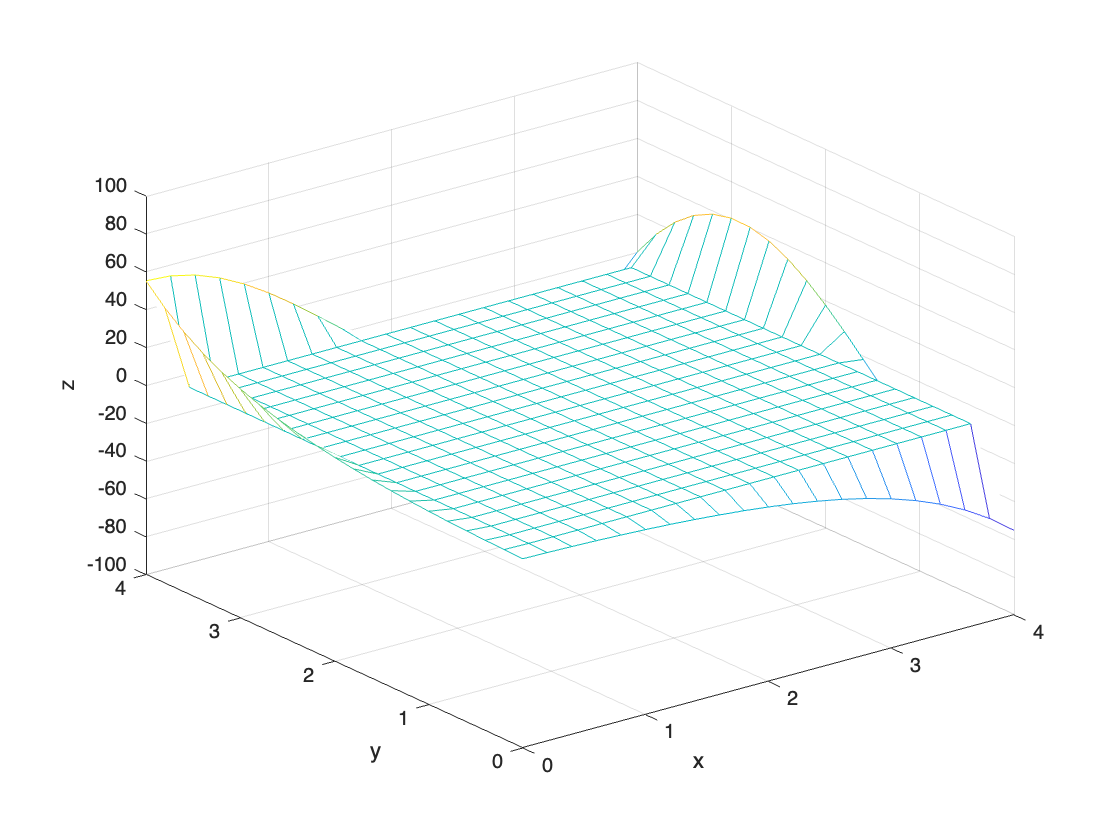

f = inline('0','x','y'); g = inline('0','x','y');
x0 = 0; xf = 4; Mx = 20; y0 = 0; yf = 4; My = 20;
bx0 = inline('exp(y) - cos(y)','y'); %(E9.1.2a)
bxf = inline('exp(y)*cos(4) - exp(4)*cos(y)','y'); %(E9.1.2b)
by0 = inline('cos(x) - exp(x)','x'); %(E9.1.3a)
byf = inline('exp(4)*cos(x) - exp(x)*cos(4)','x'); %(E9.1.3b)
D = [x0 xf y0 yf]; MaxIter = 500; tol = 1e-4;
[U,x,y] = poisson(f,g,bx0,bxf,by0,byf,D,Mx,My,tol,MaxIter);

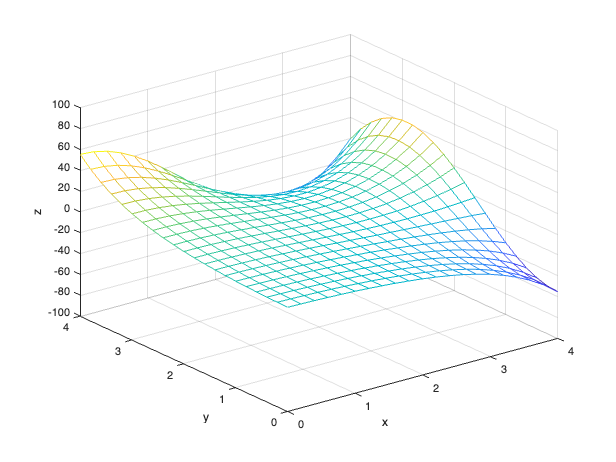

clf, mesh(x,y,U), axis([0 4 0 4 -100 100])
xlabel('x'), ylabel('y'), zlabel('z')

function [u,x,y] = poisson(f,g,bx0,bxf,by0,byf,D,Mx,My,tol,MaxIter)
    %solve u_xx + u_yy + g(x,y)u = f(x,y)
    % over the region D = [x0,xf,y0,yf] = {(x,y) |x0 <= x <= xf, y0 <= y <= yf}
    % with the boundary Conditions:
    % u(x0,y) = bx0(y), u(xf,y) = bxf(y)
    % u(x,y0) = by0(x), u(x,yf) = byf(x)
    % Mx = # of subintervals along x axis
    % My = # of subintervals along y axis
    % tol : error tolerance
    % MaxIter: the maximum # of iterations
    
    x0 = D(1); xf = D(2); y0 = D(3); yf = D(4);
    dx = (xf - x0)/Mx; 
    x = x0 + [0:Mx]*dx;
    dy = (yf - y0)/My; 
    y = y0 + [0:My]'*dy;
    Mx1 = Mx + 1; 
    My1 = My + 1;
    
    %Boundary conditions
    for m = 1:My1
        u(m,[1 Mx1])=[bx0(y(m)) bxf(y(m))]; 
    end %left/right side
    for n = 1:Mx1 
        u([1 My1],n) = [by0(x(n)); byf(x(n))]; 
    end %bottom/top
    
    %initialize as the average of boundary values
    sum_of_bv = sum(sum([u(2:My,[1 Mx1]) u([1 My1],2:Mx)']));
    u(2:My,2:Mx) = sum_of_bv/(2*(Mx + My - 2));
    for i = 1:My
        for j = 1:Mx
        F(i,j) = f(x(j),y(i)); G(i,j) = g(x(j),y(i));
        end
    end
    
    mesh(x,y,u)
    axis([0 4 0 4 -100 100])
    xlabel('x'), ylabel('y'), zlabel('z')
    
    %Eq.(9.1.6)
    dx2 = dx*dx; dy2 = dy*dy; dxy2 = 2*(dx2 + dy2);
    rx = dx2/dxy2; ry = dy2/dxy2; rxy = rx*dy2;
    
    for itr = 1:MaxIter
        for j = 2:Mx
            for i = 2:My
            u(i,j) = ry*(u(i,j + 1)+u(i,j - 1)) + rx*(u(i + 1,j)+u(i - 1,j))...
            + rxy*(G(i,j)*u(i,j)- F(i,j)); %Eq.(9.1.5a)
            end
        end
        if itr > 1 && max(max(abs(u - u0))) < tol, break; end
        u0 = u;
    end
end